# Test script for basic TANDEM-STRAIGHT analysis and synthesis

clear
%   Please use this in "cell mode"

## Initialize conditions        %条件を初期化

directoryBase = [pwd '/'];
filename_save = 'sample1-2-1_normalization70dB';
fileName = [filename_save '.wav'];

noisy = 0; % If the speech material consists of low frequency noise, set this vaviable 1;
plotFigures = 1; % If you do not need plots, set this variable 0.

## Read speech data from a file   %ファイルから音声データを読み取る

[x,fs] = audioread([directoryBase fileName]);
X = x;

x = x(:,1); %   Make sure it is a comum vector.
soundsc(x,fs) % Playback sound

## Extract source information    %ソース情報を抽出する

r = exF0candidatesTSTRAIGHTGB_ver2(x,fs) % Extract F0 information、「framePeriod」を変更した「exF0candidatesTSTRAIGHTGB.m」を使用

r = フィールドをもつ struct :
         samplingFrequency: 16000
    dateOfSourceExtraction: '11-Feb-2021 02:40:13'
         controlParameters: [1×1 struct]
                        f0: [3590×1 double]
          periodicityLevel: [3590×1 double]
            periodicityMap: [513×3590 double]
         temporalPositions: [1×3590 double]
           f0CandidatesMap: [5×3590 double]
      f0CandidatesScoreMap: [5×3590 double]
      f0candidatesPowerMap: [5×3590 double]
          elapsedTimeForF0: 44.9453
            statusParamsF0: [1×1 struct]


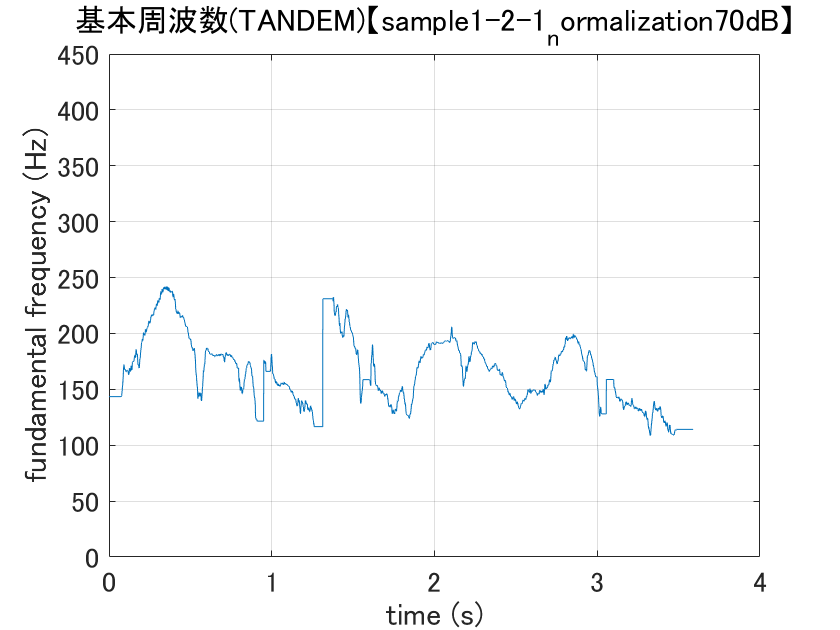


if noisy
    x = removeLF(x,fs,r.f0,r.periodicityLevel); % Low frequency noise remover
    r = exF0candidatesTSTRAIGHTGB_ver2(x,fs)
end;

rc = autoF0Tracking(r,x); % Clean F0 trajectory by tracking
rc.vuv = refineVoicingDecision(x,rc);

if plotFigures
    figure;
    plot(rc.temporalPositions,rc.f0);grid on
    set(gca,'fontsize',14);
    xlabel('time (s)')
    ylabel('fundamental frequency (Hz)');
    str = ['基本周波数(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
    title(str);                       %タイトル
    xlim([0 4.0]);                                             %x軸の値の範囲
    ylim([0 450]);                                             %y軸の値の範囲
%     print(str, '-dmeta');                                    %emf形式(拡張メタファイル)として保存
end;


q = aperiodicityRatioSigmoid(x,rc,1,2,0) % aperiodicity extraction

経過時間は 2.334191 秒です。
経過時間は 0.062365 秒です。
経過時間は 1.490004 秒です。
経過時間は 5.655973 秒です。


q = フィールドをもつ struct :
             samplingFrequency: 16000
        dateOfSourceExtraction: '11-Feb-2021 02:40:13'
             controlParameters: [1×1 struct]
                            f0: [3590×1 double]
              periodicityLevel: [3590×1 double]
                periodicityMap: [513×3590 double]
             temporalPositions: [1×3590 double]
               f0CandidatesMap: [5×3590 double]
          f0CandidatesScoreMap: [5×3590 double]
          f0candidatesPowerMap: [5×3590 double]
              elapsedTimeForF0: 44.9453
                statusParamsF0: [1×1 struct]
                           vuv: [3590×1 double]
              dateOfExtraction: '11-Feb-2021 02:41:08'
               stretchedSignal: [1×87190 double]
        residualMatrixOriginal: [4×3590 double]
            cutOffListOriginal: [3×1 double]
             residualMatrixFix: [4×3590 double]
                 cutOffListFix: [3×1 double]
                      targetF0: 108.6362
    solutionConditionsOriginal: [1×3 s

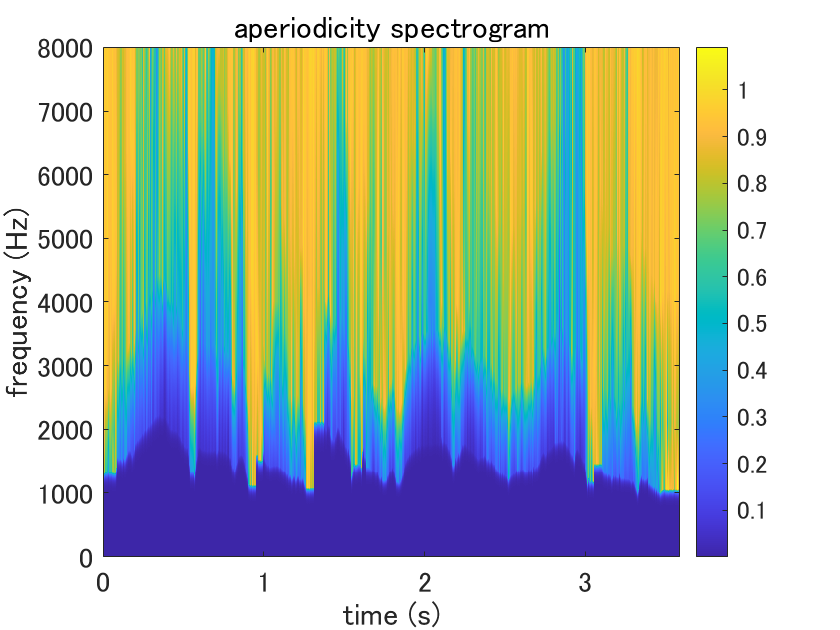


if plotFigures;
    displayAperiodicityStructure(q,1);
end;

## Extract spectral informatiopn    %スペクトル情報を抽出する

f = exSpectrumTSTRAIGHTGB_ver2(x,fs,q)    %「framePeriod」を変更した「exSpectrumTSTRAIGHTGB.m」を使用

f = フィールドをもつ struct :
      ElapsedTimeForSpectrum: 2.1475
           temporalPositions: [1×3590 double]
         spectrogramSTRAIGHT: [513×3590 double]
           samplingFrequency: 16000
    TANDEMSTRAIGHTconditions: [1×1 struct]
           spectrogramTANDEM: [513×3590 double]
    dateOfSpectrumEstimation: '11-Feb-2021 02:41:14'


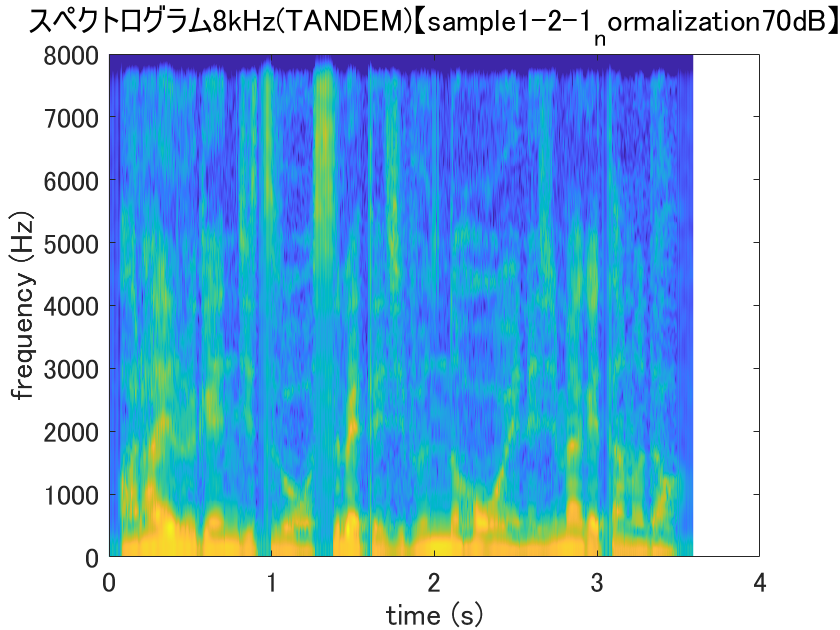


STRAIGHTobject.waveform = x;
STRAIGHTobject.samplingFrequency = fs;
STRAIGHTobject.refinedF0Structure.temporalPositions = r.temporalPositions;
STRAIGHTobject.SpectrumStructure.spectrogramSTRAIGHT = f.spectrogramSTRAIGHT;
STRAIGHTobject.refinedF0Structure.vuv = rc.vuv;
f.spectrogramSTRAIGHT = unvoicedProcessing(STRAIGHTobject);

sgramSTRAIGHT = 10*log10(f.spectrogramSTRAIGHT);
maxLevel = max(max(sgramSTRAIGHT));
figure;
imagesc([0 f.temporalPositions(end)],[0 fs/2],max(maxLevel-80,sgramSTRAIGHT));
axis('xy')
set(gca,'fontsize',14);
xlabel('time (s)')
ylabel('frequency (Hz)');
% str = ['スペクトログラム(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
str = ['スペクトログラム8kHz(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
xlim([0 4.0]);                                         %x軸の値の範囲
ylim([0 8000]);                                        %y軸の値の範囲

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

f0raw = rc.f0';
n3sgram = sqrt(f.spectrogramSTRAIGHT);    %パワースペクトルを振幅スペクトルに変更

mat_save = [filename_save '【koharaメソッド用】'];
save(mat_save, 'X', 'fs', 'f0raw', 'n3sgram');

s = exTandemSTRAIGHTsynthNx(q,f)

constrained sigmoidal model


s = フィールドをもつ struct :
            dateOfSynthesis: '11-Feb-2021 02:41:19'
              startPosition: 0
                endPosition: 3.5890
          samplingFrequency: 16000
                    movieOn: 0
               synthesisOut: [57425×1 double]
         FFTsizeInSynthesis: 1024
    elapsedTimeForSynthesis: 1.0960


sound(s.synthesisOut/max(abs(s.synthesisOut))*0.8,fs) % old implementation

s2 = exGeneralSTRAIGHTsynthesisR2(q,f) % new implementation

s2 = フィールドをもつ struct :
         synthesisOut: [57296×1 double]
    samplingFrequency: 16000
          elapsedTime: 0.5488


sound(s2.synthesisOut/max(abs(s2.synthesisOut))*0.8,fs)